# **Fractional-order SEIQRDP Model for Simulating the Dynamics of COVID-19 Epidemic**

**Mohamed A. Bahloul, Member, IEEE, Abderrazak Chahid, Member, IEEE,and Taous-MeriemLaleg-Kirati, Associate Member, IEEE**

**Estimation, Modeling and Analysis Group, Computer,  Electrical  and  Mathematical  Sciences  and  Engineering Division, King Abdullah University of Science and Technology**

- **Goal:** Coronavirus  disease  (COVID-19)  is  a  contagious   disease   caused   by   a   newly   discovered   coronavirus, initially   identified   in   the   mainland   of   China,   late   December 2019.   COVID-19   has   been   confirmed   as   a   higher   infectious disease   that   can   spread   quickly   in   a   community   population depending  on  the  number  of  susceptible  and  infected  cases  andalso   depending   on   their   movement   in   the   community.   Since January  2020,  COVID-19  has  reached  out  to  many  countries worldwide,  and  the  number  of  daily  cases  remains  to  increaserapidly. 

- **Method: **Several mathematical and statistical models havebeen  developed  to  understand,  track,  and  forecast  the  trend of   the   virus   spread. ***Susceptible-Exposed-Infected-Quarantined-Recovered-Death-Insusceptible*** (SEIQRDP) model  is  one  of  themost  promising  epidemiological  models  that  has  been  suggested for estimating the transmissibility of the COVID-19. In the present study, we propose a fractional-order SEIQRDP model to analyzethe COVID-19 pandemic. In the recent decade, it has proven that many aspects in many domains can be described very successfully using  fractional  order  differential  equations.  Accordingly,  the Fractional-order  paradigm  offers  a  flexible,  appropriate,  andreliable framework for pandemic growth characterization. In fact, due to its non-locality properties, a fractional-order operator takesinto  consideration  the  variables’  memory  effect,  and  hence,  ittakes  into  account  the  sub-diffusion  process  of  confirmed  andrecovered cases.

- **Results:** The validation of the studied fractional-order  model  using  real  COVID-19  data  for  different  regions  in  Nouvelle-Aquitaine-France region show  the  potential  of  the  proposed paradigm in predicting and understanding the pandemic dynamic.

- **Conclusions:** Fractional-order epidemiological models might playan important role in understanding and predicting the spread ofthe COVID-19, also providing relevant guidelines for controllingthe  pandemic.

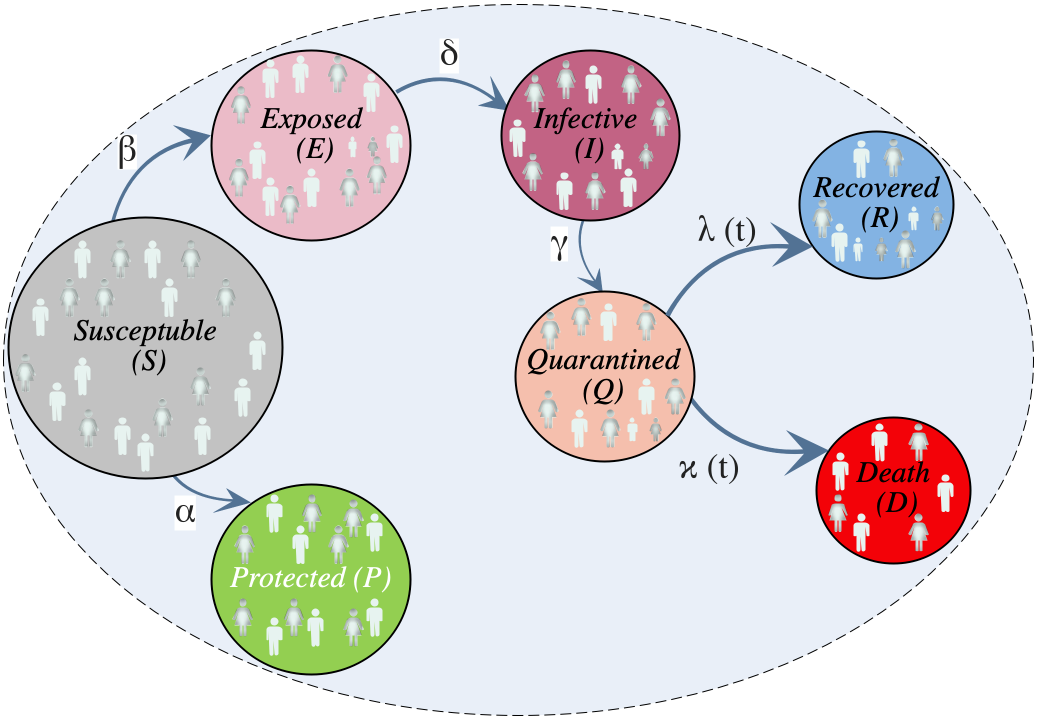

### SEIQRDP compartment epidemic model showing the protection rate, α, the infection rate, β, the inverse of the average latent time, γ, the rate at which infectious people enter in quarantine, δ, the time dependent cure rate, λ(t), and the time dependent mortality rate κ(t)

***Here we present the code for the validation of the Nouvelle-Aquitaine-France region pandemic spreading. Some functions in this code have been adopted from [1].***

***[1]: E.  Cheynet,  “Generalized  seir  epidemic  model  (fitting  and  computa-tion)(https://www.  github.  com/echeynet/seir),  github,”Retrieved  April,vol. 6, p. 2020, 2020***

clear all;
close all;
clc;

load('data.mat')
Ntest=5;
Npop= 5.987e6;

alpha_i = 0; 
beta_i = 0; 
LT_i = .5; 
Q_i = 0.5; 
lambda_i = [0.1,0.05]; 
kappa_i = [0.1,0.05]; 
guess = [alpha_i,beta_i,1/LT_i, Q_i,lambda_i,kappa_i];

E0 = Confirmed(1); % Initial number of exposed cases. Unknown but unlikely to be zero.
I0 = Confirmed(1); % Initial number of infectious cases. Unknown but unlikely to be zero.
Q0 = Confirmed(1)-Recovered(1)-Deaths(1);
R0 = Recovered(1);
D0 = Deaths(1);
Active = Confirmed-Recovered-Deaths;

q0=1*[1,1,1,1,1,1,1];
guess1 = [guess, q0];

[alpha2,beta2,gamma2,delta2,Lambda2,Kappa2,q2] = fit_FSEIQRDP(Active(1:end-Ntest),Recovered(1:end-Ntest),Deaths(1:end-Ntest),Npop,E0,I0,time(1:end-Ntest),guess1,'Display','off');

dt = .1; % time step
time1 = datetime(time(1)):dt:datetime(datestr(floor(datenum(now))-datenum(90)));
N = numel(time1);
t = [0:N-1].*dt;
[Sf1,Ef1,If1,Qf1,Rf1,Df1,Pf1] = FSEIQRDP(alpha2,beta2,gamma2,delta2,Lambda2,Kappa2,q2,Npop,E0,I0,Q0,R0,D0,t);

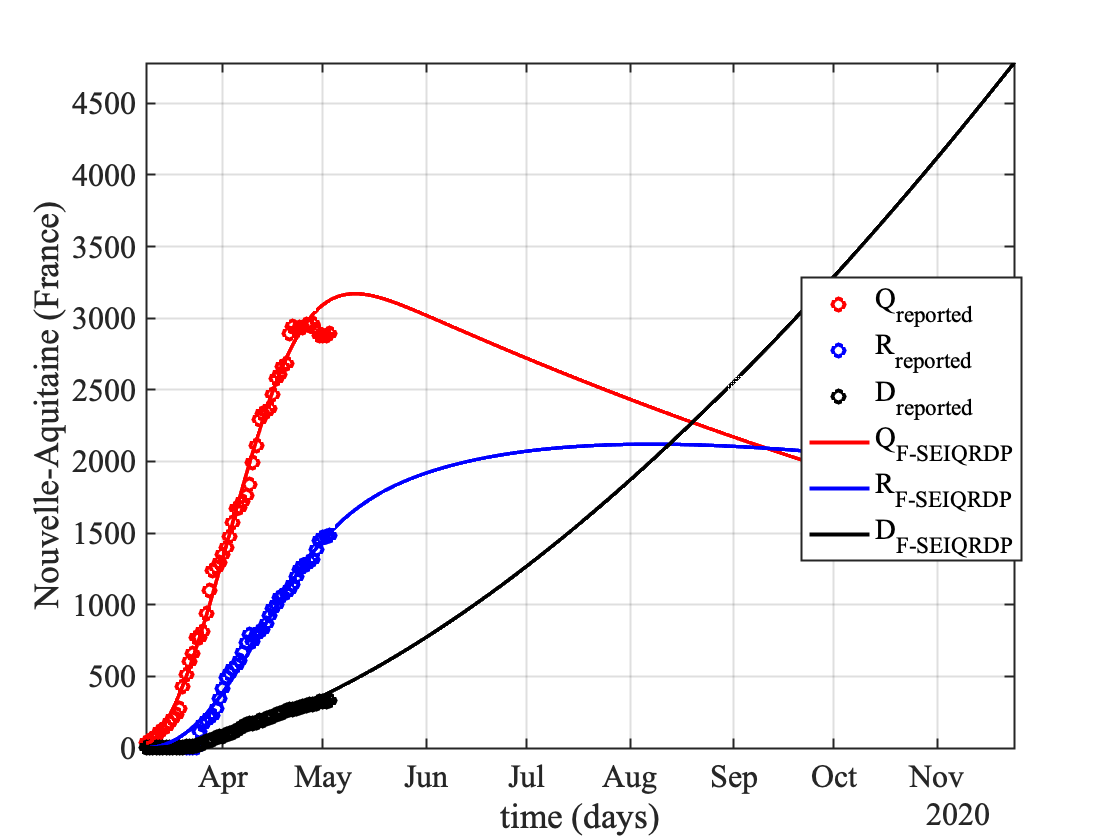

figure
plot(time,Active,'ro',time,Recovered,'bo',time,Deaths,'ko','LineWidth',2);
hold on
plot(time1,Qf1,'r',time1,Rf1,'b',time1,Df1,'k','LineWidth',2);
ylabel('Nouvelle-Aquitaine (France)');
xlabel('time (days)')
leg = {'Q_{reported}','R_{reported}','D_{reported}','Q_{F-SEIQRDP}','R_{F-SEIQRDP}','D_{F-SEIQRDP}'};
lh =legend(leg{:});              
lh.Position(2) = 0.5 - lh.Position(4)/2;
set(gcf,'color','w')
grid on
axis tight
set(gca,'fontname','times','FontSize', 16,'yscale','lin','LineWidth',1)